clear all;close all;
load("Observation_wb_test.mat");

Listen to the sounds of the first sensor using soundsc command.

%soundsc(real(X(:,1)),fs);

Plot the wave in time domain with x-axis represented by t (s) and plot the magnitude of the frequency response and represent x-axis in frequency (Hz).

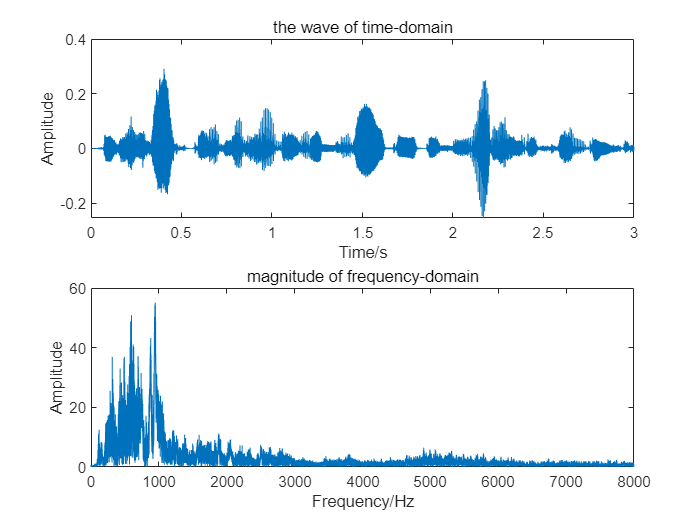

c = 340; 
fftx = fft(real(X(:,1)));
[N,nSensors] = size(X);
t = (0:N-1)/fs;
f = fs/N*(0:round(N/2)-1);
figure;
subplot(2,1,1);plot(t,real(X(:,1)));
title("the wave of time-domain");xlabel('Time/s');ylabel('Amplitude');
subplot(2,1,2);plot(f,abs(fftx(1:round(N/2))));
title("magnitude of frequency-domain");xlabel('Frequency/Hz');ylabel('Amplitude');

Perform short-time Fourier analysis on the observations. Divide the observations into different segments, and each segment is regarded as a stationary signal. Then do discrete Fourier analysis for each segment.

winlen = 512;
winmov = 256;
ms = floor((N-winlen+winmov)/winmov)+1;
Xs = zeros(ms,512,nSensors);
win = hann(512);

for i = 1:nSensors
    for j = 1:ms
        try
            Xs(j,:,i) = fft((X((1+256*(j-1)):(512+256*(j-1)),i).*win).');
        catch
        end
    end
end

Treat the same frequency band in all divisions as narrow-band and perform narrowband MUSIC algorithm in each frequency band.

n_source = 2;                                          
dx = 0.025;                                            
dy = 0;                                                                                                                      
Index = linspace(0,nSensors-1,nSensors);
p = (-(nSensors-1)/2 + Index.') * [dx dy];

stride = 1;                                               
theta = -90:stride:90;
v =  [sind(theta);-cosd(theta)]; 

P_sm = zeros(length(theta),1);
for k = 1:winlen/2
    tempx = squeeze(Xs(:,k,:));
    tempfs = (k-1)/512*fs;
    P_sm = P_sm + MUSIC_nb(tempx,tempfs,p,v,n_source,c);
end
P_sm = 1./P_sm;

Acquire the overall pseudo spatial spectrum, plot it, and give the DOA estimation result in the report.

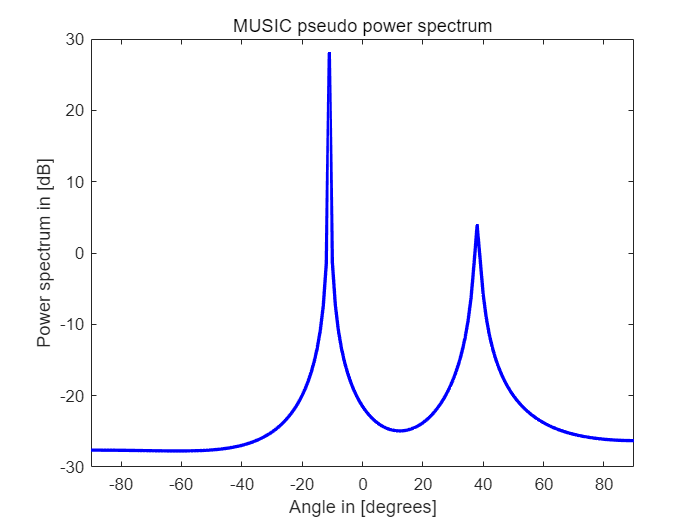

figure;
linspec = {'b-','LineWidth',2};
plot(theta, 10*log10(abs(P_sm)), linspec{:});
title('MUSIC pseudo power spectrum')
xlabel('Angle in [degrees]');
ylabel('Power spectrum in [dB]');
xlim([-90,90]);

P_middle = abs(P_sm(2:end-1));
P_front = abs(P_sm(1:end-2));
P_back = abs(P_sm(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(P_sm(1));P_middle;abs(P_sm(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -11 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 38 deg


function P_sm = MUSIC_nb(tempx,tempfs,p,v,n_source,c)                                   
    [tempN,~] = size(tempx);
    f_c = tempfs;
    R_x = (tempx.'*(tempx.')')/tempN;                                               
    a_theta = exp(-1j*2*pi/c*f_c*p*v);      

    [EV,~] = eig(R_x);     
    Un = EV(:,1:end-n_source);                                   
    P_sm = diag(a_theta'*(Un*Un')*a_theta);                 
end